# Quadruped's spine optimizer

# Step 2  - Optimize quadruped with spine 

Script is trying to teach a quadruped robot to walk and finding parameters of spine using a genetic algorithm. Write name files with trajectory and variables.

## Run previous model

clc; clear all;
typeBody = 1;
use_previous = 0;

Folder with file:

addpath(genpath('ResultOptimizeSpine')) 

 Name of file with data:

path_prev = 'bouncing_1_PD_ctrl_optimizedData_20Apr22_1317';

Run plot figures, and write parameters:

run_previous;
PlotCoM_xyz;

disp(['Main characteristics. Mean Z position: ' num2str(mean_Z) ...
       ' [m], mean velocity forward: ' num2str(mean_velocity)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

## Set parameters optimize

Define desired velocity, height and geit period. You also can choose type control of legs.

robotParameters; % Paramaters of robot and simulation
typeBody = 2; % Body's type is without spine 
numPoints = 6; % Number of joint angle points
mdlName = 'QR_Unitree'; % Main model
open_system(mdlName);

Choose type control of legs: 1 - Motor; 2 - PD control

actuatorType = 2;

Set desired velocity for optimization, [m/s]:

v_des = 1.5;

Set desired mean z position, [m]:

z_des = 0.4;

Period of walking gait, [s]:

gait_period = 0.5;

To reduce the search space, scale the angle waypoints and solve the optimization algorithm with integer parameters. This scaling factor is from degrees to an integer.

scalingFactor = 3;

Create initial conditions to seed the previus population for optimization.

% You can fill inital population previous data 
use_previous = false;
if use_previous
    run_previous;
    p0 = [femur_motionFront(1:end-1),...
        tibia_motionFront(1:end-1),...
        femur_motionRear(1:end-1),...
        tibia_motionRear(1:end-1),...
        delta_gait_front, delta_gait_rear]/scalingFactor;
end

## Set options genetic algorithm

Define options genetic algorithm and optimization

Compile the model to run a single simulation faster:

accelFlag = false;

**Not recommend use! **Use parallel computing on multiple cores on your machine or on a cluster or cloud

parallelFlag = false;  

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

Set size of population GA

opts = optimoptions('ga');
population_size = 30;

Set maximum of generation

opts.MaxGenerations = 10;

Options for GA:

opts.Display = 'iter';
opts.PopulationSize = population_size;
opts.PlotFcn = {@gaplotbestf, @gaplotexpectation}; 
if use_previous
    opts.InitialPopulationMatrix = repmat(p0,[population_size 1]);
end

## Set joint angle bounds and constraints

upperBnd = [-90*ones(1,numPoints), ... % Femur Front Leg 
            120*ones(1,numPoints), ... % Tibia Front Leg 
            -90*ones(1,numPoints), ... % Femur Rear Leg 
            120*ones(1,numPoints), ... % Tibia Rear Leg 
            10*ones(1,2), ... % Delay in percent
            zeros(1,3)];
lowerBnd = [-160*ones(1,numPoints), ... % Femur Front Leg
            30*ones(1,numPoints), ... % Tibia Front Leg
            -160*ones(1,numPoints), ... % Femur Rear Leg 
            30*ones(1,numPoints), ... % Tibia Rear Leg 
            -10*ones(1,2), ... % Delay in percent
            zeros(1,3)];

% Equilibrium position
upperBnd(end-2) = pi/12;
lowerBnd(end-2) = -pi/12;

% Stiffness
upperBnd(end-1) = 300;
lowerBnd(end-1) = 50;

% Damphing
upperBnd(end) = 200;
lowerBnd(end) = 50;

upperBnd = upperBnd/scalingFactor;
lowerBnd = lowerBnd/scalingFactor;

Run commands to set up parallel/accelerated simulation

doSpeedupTasks;

## Run optimization

Set the function CostFuncOptimizeSpine.m how Cost Of Function GA

costFcn = @(p)CostFuncOptimizeSpine(p,mdlName,scalingFactor,gait_period, v_des, actuatorType, z_des);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 30, Max Generations: 10


Run genetic algorithm:


Single objective optimization:
29 Variable(s)
29 Integer variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1               60            2392       1.238e+07        0
    2               85            42.2       2.134e+07        0
    3              110            42.2       4.855e+06        1
    4              135           14.97       7.027e+06        0
    5              160           14.97       1.224e+07        1
    6              185           14.97       4.827e+06        2
    7              210           14.97        3.09e+06        3
    8              235           14.97       2.846e+06        4
    9              260           5.987       3.079e+06        0
   10              285           2.931       2.108e+06

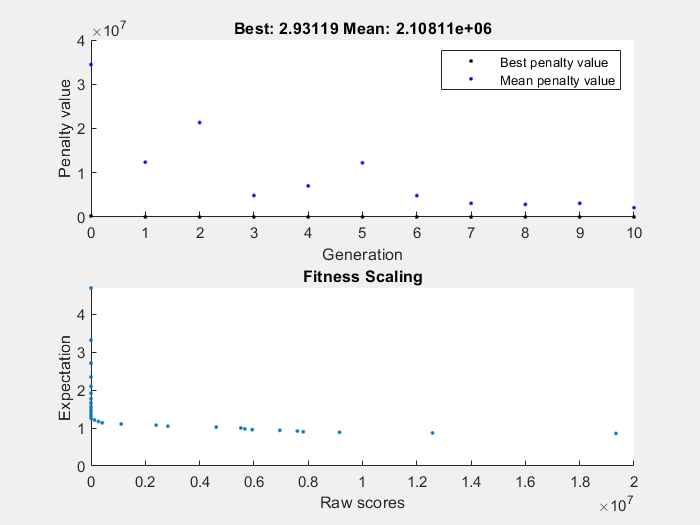

Optimization terminated: maximum number of generations exceeded.


[pFinal,reward,~,output,last_population,last_scores] = ga(costFcn,numPoints*4+5,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],1:(numPoints*4+5),opts);

disp(['Final reward function value: ' num2str(reward)])

Final reward function value: 2.9312


set_param(mdlName,'SimMechanicsOpenEditorOnUpdate','on'); % On Mechanics Explorers
set_param(mdlName,'FastRestart','off'); % Off Fast Restart
delete(gcp('nocreate')); % Shutdown parallel pool

## Analyze and save results

Convert from optimization integer search space to trajectories in radians

indiv = 1; % The best individ is first
pScaled = scalingFactor*last_population(indiv,:);
reward = last_scores(indiv,:);
traj_times = linspace(0,gait_period,numPoints+1);
femur_motionFront = deg2rad([pScaled(1:numPoints) pScaled(1)]);
tibia_motionFront = deg2rad([pScaled(numPoints+1:2*numPoints) pScaled(numPoints+1)]);
femur_motionRear = deg2rad([pScaled(2*numPoints+1:3*numPoints) pScaled(2*numPoints+1)]);
tibia_motionRear = deg2rad([pScaled(3*numPoints+1:4*numPoints) pScaled(3*numPoints+1)]);

delta_gait_front = pScaled(end-4);
delta_gait_rear = pScaled(end-3);

bd_spine_eq_pos = pScaled(end-2);
bd_spine_stiffness = pScaled(end-1);
bd_spine_damping = pScaled(end);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
[q_fr,fem_der_front,tib_der_front] = createSmoothTrajectory(femur_motionFront,tibia_motionFront,gait_period,evalTimes);
[q_rr,fem_der_rear,tib_der_rear] = createSmoothTrajectory(femur_motionRear,tibia_motionRear,gait_period,evalTimes);

Plot the resulting trajectory

figure
subplot(2,1,1)
plot(evalTimes,rad2deg(q_fr(1,:)),'b-',traj_times,rad2deg(femur_motionFront),'ro');
title('Final Optimized Gait for Front Legs')
xlabel('Time [s]');
ylabel('Hip Angles [deg]');
subplot(2,1,2)
plot(evalTimes,rad2deg(q_fr(2,:)),'b-',traj_times,rad2deg(tibia_motionFront),'ro');
xlabel('Time [s]');
ylabel('Knee Angles [deg]');
figure
subplot(2,1,1)
plot(evalTimes,rad2deg(q_rr(1,:)),'b-',traj_times,rad2deg(femur_motionRear),'ro');
title('Final Optimized Gait for Rear Legs')
xlabel('Time [s]');
ylabel('Hip Angles [deg]');
subplot(2,1,2)
plot(evalTimes,rad2deg(q_rr(2,:)),'b-',traj_times,rad2deg(tibia_motionRear),'ro');
xlabel('Time [s]');
ylabel('Knee Angles [deg]');

Save results to a timestamped MAT-file

choice_ctrl_legs;
if v_des < 0.9
    type_locomotion = 'walk';
elseif v_des >= 0.9 && v_des < 1.5
    type_locomotion = 'trot';
elseif v_des >= 1.5 
    type_locomotion = 'bouncing';
end
save_actType = actuatorType;
save_bodyType = typeBody;
strFile = '';
outFileName = ['ResultOptimizeSpine/' type_locomotion '_' indiv '_' ctrl_name '_optimizedData_' datestr(now,'ddmmmyy_HHMM')];
for idx1 = 1:numel(outFileName)
    strFile = strcat(strFile,outFileName(idx1));
end
save(strFile,...
    'reward','gait_period','traj_times','femur_motionFront','tibia_motionFront',...
    'delta_gait_front','femur_motionRear','tibia_motionRear','delta_gait_rear',...
    'save_actType','save_bodyType',...
    'spine_damphing_coeff', 'spine_postion', 'spine_spring_stiff');

Path to the file with optimize's trajectory:

disp(strFile);

## Simulate optimize model and plot figures

typeBody = 1;
use_previous = 0;
path_prev = strFile; % Run model with previos section trajectory
run_previous;

PlotCoM_xyz;
disp(['Mean Z position: ' num2str(mean_Z) ...
       ' [m], mean velocity forward: ' num2str(mean_velocity)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

## Cleanup

Close the model and, if a parallel pool was created, delete it.

doCleanup = false;
if doCleanup
    close all force; % Clear figures
    bdclose(mdlName);
    if parallelFlag
        delete(gcp('nocreate'));
    end
end